## FIltro de Kalman Estendido -- Capítulo 9

A dinâmica do problema se dá por meio de um radar que deseja rastrear um bala de canhão (*target*). O radar se encontra um posição dada fixa dada por $\left(x_r ,y_r \right)$e uma bala de canhão é lançada da posição inicial $\left(0,0\right)$ e tem a sua posição dada por $\left(x_T ,y_T \right)$, conforme figura abaixo:

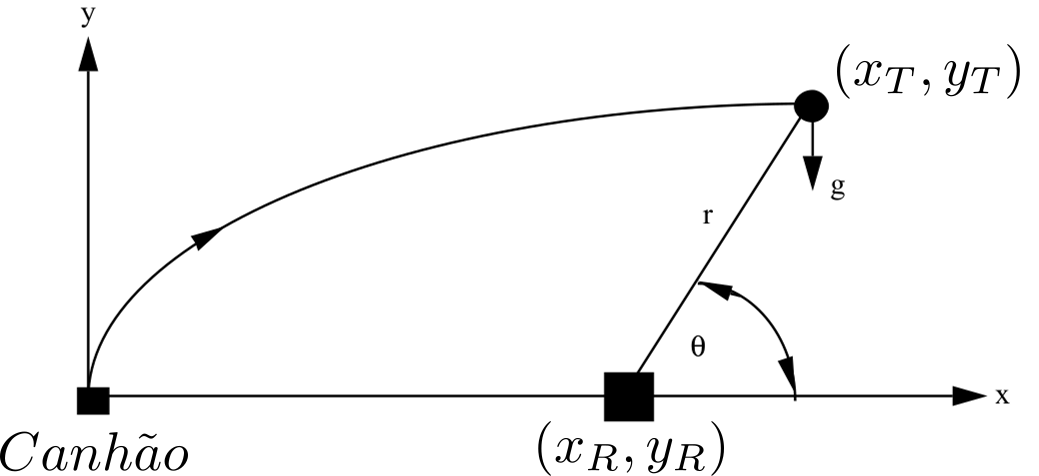

A física por trás desse problema diz respeito apenas a gravidade $\left(g\right)$ agindo sobre o projétil após o mesmo ter sido atirado. Pela figura, consegue-se encontrar uma relação matemática para expressar a distância entre o radar e a bala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$, dados por:


$$\theta ={\mathrm{tan}}^{-1} \left(\frac{y_T -y_r }{x_T -x_r }\right)$$



$$r=\sqrt{\text{ }{\left(x_T -x_r \right)}^2 +{\left(y_T -y_r \right)}^2 }$$


A ideia por trás de se aplicar o filtro de Kalman Estendido no referido problema é fazer a estimação de velocidade e posição do projétil por meio de medidas obtidas pelo radar. Antes de aplicarmos propriamente o Filtro de Kalman, precisamos construir um modelo matemático que represente a posição e velocidade do projétil dada as variáveis $\theta \text{ }$e $r$. Sendo assim, tem-se que:


$$x_T =r\text{ }\mathrm{cos}\left(\theta \text{ }\right)+x_R$$



$$y_T =r\text{ }\mathrm{sen}\left(\theta \text{ }\right)+{y_R }$$


Sendo conhecida a posição do radar, as medidas obtidas por ele são ruidosas. Sendo assim, para se estimar a posição do corpo baseada apenas nas medidas do radar, a gente poderia proceder da seguinte forma:


$$\hat{x_T } =r^∗ \text{ }\cos \left(\theta^∗ \text{ }\right)+x_R$$



$$\hat{y_T } =r^∗ \text{ }\text{sen}\left(\theta^∗ \text{ }\right)+y_R$$


Para a determinação de velocidade, podemos utilizar a definição do cálculo, em que:


$$\hat{\dot{x_T } } =\frac{{\hat{x} }_{T_k } -{\hat{x} }_{T_{k-1} } }{T_s }$$



$$\hat{\dot{y_T } } =\frac{{\hat{y} }_{T_k } -{\hat{y} }_{T_{k-1} } }{T_s }$$


A grande problemática de se utilizar essa metodologia para determinação de posição e velocidade é que a gente utiliza os dados brutos obtidos pelo radar e reproduz a física dele. Não existe estimação no sentido estrito da palavra.

Para fazermos uso do Filtro de Kalman, a gente pode descrever a dinâmica do projeto em estados de espaço da forma:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_T \\
{\ddot{x} }_T \\
{\dot{y} }_T \\
{\ddot{y} }_T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_T \\
{\dot{x} }_T \\
y_T \\
{\dot{y} }_T 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
-g
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
u_{s_1 } \\
0\\
u_{s_2 } 
\end{array}\right\rbrack$$


em que $u_s$ é um ruído adicionado ao termo de aceleração do como forma de proteção contra possíveis efeitos que não tenham sido considerados no Filtro de Kalman. Olhando a equação do sistema, tem-se que:


$$F=$$

$$\left\lbrack \begin{array}{c}
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Como a matriz fundamental é invariante ao tempo, tem-se que:


$$\Phi \left(t\right)=I+\mathrm{Ft}+\frac{F^2 t^2 }{2!}+\frac{F^3 t^3 }{3!}+\dots$$


Se você executar as multiplicação, encontrará que:


$$F^2 =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


e portanto:


$$\Phi \left(t\right)=I+\text{Ft}=\left\lbrack \begin{array}{c}
1 & t & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & t\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 

A tempo discreto, nos instantes de amostragem $\left(T_s \right)$, tem-se que:


$$\Phi_k =\left\lbrack \begin{array}{c}
1 & T_s  & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & T_s \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Dada a escolha cartesiana do vetor de estados, as medidas de $\theta \text{ }$e $r$ são funções não lineares dos elementos do vetor de estados. Mais precisamente, tem-se que:


$$\left\lbrack \begin{array}{c}
\Delta \theta {\text{ }}^∗ \\
\Delta r{\text{ }}^∗ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_T }\theta \text{ } & \frac{\partial }{\partial {\dot{x} }_T }\theta \text{ } & \frac{\partial }{\partial y_T }\theta \text{ } & \frac{\partial }{\partial {\dot{y} }_T }\theta \text{ }\\
\frac{\partial }{\partial x_T }r & \frac{\partial }{\partial {\dot{x} }_T }r & \frac{\partial }{\partial y_T }r & \frac{\partial }{\partial {\dot{y} }_T }r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta x}_T \\
{\dot{\Delta x} }_T \\
{\Delta y}_T \\
{\dot{\Delta y} }_T 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
v_{\theta \text{ }} \\
v_r 
\end{array}\right\rbrack$$


em que $v_{\theta \text{ }}$e $v_r$ representam os ruidos de medida, respectivamente. Para a determinação da matriz $H$é importante que derivamos parcialmente as funções uma a uma, resultando em:


$$H=\left\lbrack \begin{array}{c}
\frac{-\left(y_T -y_R \right)}{r^2 } & 0 & \frac{\left(x_T -x_R \right)}{r^2 } & 0\\
\frac{\left(x_T -x_R \right)}{r} & 0 & \frac{\left(y_T -y_R \right)}{r} & 0
\end{array}\right\rbrack$$


A matriz $R$ é dada por:


$$R=E\left({\mathrm{vv}}^T \right)=E\left(\left\lbrack \begin{array}{c}
v_{\theta \text{ }} \\
v_r 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_{\theta }  & v_r 
\end{array}\right\rbrack \right)=E\left(\left\lbrack \begin{array}{c}
v_{\theta }^2  & 0\\
0 & v_r^2 
\end{array}\right\rbrack \right)=\left\lbrack \begin{array}{c}
{\sigma_{\theta } }^2  & 0\\
0 & {\sigma_r }^2 
\end{array}\right\rbrack$$


em que:

- $E\left(v_{\theta }^2 \right)=$${\sigma_{\theta } }^2$;

- $E\left(v_r^2 \right)=$${\sigma_r }^2$; e

-  as medidas são consideradas descorrelacionadas (ou seja, $v_{\theta }$$v_r =0$).

Para a determinação da matriz Q, tem-se que:


$$Q\left(t\right)=E\left({\text{ww}}^T \right)=E\left(\left\lbrack \begin{array}{c}
0\\
{u_s }_1 \\
0\\
u_{s_2 } 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & u_{s_1 }  & 0 & u_{s_2 } 
\end{array}\right\rbrack \right)=E\left(\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & u_{s_1 }^2  & 0 & u_{s_1 } u_{s_2 } \\
0 & 0 & 0 & 0\\
0 & u_{s_1 } u_{s_2 }  & 0 & u_{s^2 } 
\end{array}\right\rbrack \right)=$$

$$\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & \Phi_{s_1 }  & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & \Phi_{s_2 } 
\end{array}\right\rbrack$$


em que $\Phi_{s_1 }$ e $\Phi_{s_2 }$ é a densidade espectral do ruído branco assumido agindo nas duas acelerações do sistema, há o descorrelacionamento entre elas (por isso que foi considerado $\left.E\left(u_{s_1 } u_{s_2 } \right)=0\right)$ e no final das contas se considerou que $E\left(u_{s_1 }^2 \right)=E\left(u_{s_2 }^2 \right)=\Phi_s$. Tem-se que ser determinada essa matriz a tempo discreto, ela é dada por:


$$Q_k =\int_0^{T_s } \Phi \text{ }\left(\tau \text{ }\right)Q\left(t\right)\Phi {\text{ }}^T \left(\tau \text{ }\right)d\tau \text{ }$$


Então, tem-se que:


$$Q_k =\Phi_s \int_0^{T_s } \left\lbrack \begin{array}{c}
1 & \tau  & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & \tau \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1 & 0 & 0 & 0\\
\tau  & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & \tau  & 1
\end{array}\right\rbrack d\tau \text{ }$$


Que após algumas multiplicações e integração resulta em:


$$Q_k =\left\lbrack \begin{array}{c}
\frac{T_s^3 }{3} & \frac{T_s^2 }{2} & 0 & 0\\
\frac{T_s^2 }{2} & T_s  & 0 & 0\\
0 & 0 & \frac{T_s^3 }{3} & \frac{T_s^2 }{2}\\
0 & 0 & \frac{T_s^2 }{2} & T_s 
\end{array}\right\rbrack$$


Sendo assim, tem-se todas as equações necessárias para a realização da filtragem de Kalman Estandida.

Inicialmente, irei limpar todas as variáveis e janelas que possa existir.

clear; close all; clc;

Em seguida, irei fazer as setagens de alguns parâmetros do meu sistema, como:

- Tempo de amostragem; e

- Passo de integração.

% =========================================================================
% Feito por: Eduardo H. Santos
%
% Data: 04/10/2019
% =========================================================================
clear; close all; clc;

% Tempo de amostragem do sinal e 
Ts   = 1;
h    = 0.001;

Setagem da condição inicial de lançamento do projétil:

% =========================================================================
%
%       Tratativas realizadas para o objeto perseguido pelo radar
%
% =========================================================================
% Setagem inicial (ângulo e velocidade de disparo).
ang0 = 45;
v0   = 3000;
g    = 32.2;

% Matriz do sistema (os estados evoluem de maneira linear).
A = [0 1 0 0;
     0 0 0 0;
     0 0 0 1;
     0 0 0 0];
B = [ 0; 0; 0; -g];

Resultado em um vetor de estados inicial dado por:

% Vetor na condição inicial.
X{1} = [0; v0*cos(ang0*pi/180); 0; v0*sin(ang0*pi/180)];

A seguir, eu coloco as informaçoes pertinentes ao radar.

% =========================================================================
%
%                                   Radar
%
% =========================================================================
% Posição do radar.
x_radar = 100000;            
y_radar = 0;

% Característica do ruído do radar relacionado à medida de distância.
sigma_raio  = 100;
media_raio  = 0;

% Característica do ruído do radar relacionado à medida de ângulo.
sigma_theta = 0.01;
media_theta = 0;     

Vamos agora fazer as tratativas como determinação das variáveis em estudo, sejam elas a distância entre o radar e abala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$, pois são as variáveis as quais o radar efetivamente coleta.

% =========================================================================
%
%                 Informações para o Filtro de Kalman
%
% =========================================================================
% Identidade.
I    = eye(4);

% Matriz 'PHI' (do tipo 'I + F*t')
F    = [0  1  0  0;
        0  0  0  0;
        0  0  0  1;
        0  0  0  0];
% Para o instante de amostragem escolhido:
PHI  = I + (F * Ts);

% Matriz 'R' -- Essa matriz aqui não muda durante a simulação. 
R    = [sigma_theta^2         0;
              0         sigma_raio^2];
          
% Matriz Q{k} -- Aparentemente a equação do livro está errada.
Q = [(Ts^3)/3  (Ts^2)/2      0         0;
     (Ts^2)/2      Ts        0         0;
           0        0    (Ts^3)/3  (Ts^2)/2;
           0        0    (Ts^2)/2     Ts];
PHI_s = 0;
Q     = PHI_s*Q;

% Inicialização do problema (estimativas iniciais para o vetor de estados).
delta    = [ 1000; -100; -1000; 100];
X_hat{1} = X{1} + delta;
        
% Inicialização da matriz de covariância.
P0 = [delta(1)^2     0          0           0;
          0      delta(2)^2     0           0;
          0          0       delta(3)^2     0;
          0          0          0       delta(4)^2];

Nas medidas obtidas pelo radar (distância entre o radar e abala de canhão $\left(r\right)$ e o ângulo $\left(\theta \right)$), vamos fazer a inserção de ruído nos instantes em que o radar faz a amostragem do sinal:

% =========================================================================
%
%       Roda um Runge-Kuta de 2nd Ordem -- para o sistema sem ruído.
%
% =========================================================================
i = 1;
j = 1;
contadorTempo = 0;
while(X{i}(3,1) >= 0)
    
    % Base de tempo.
    tempoC(i)     = (i-1)*h;
    contadorTempo = contadorTempo + h;
    % ---------------------------------------------------------------------
    % Runge Kutta 2º Ordem -- Dinâmica do sistema.
    % Como o Live Editor não aceita 'funções', eu trouxe a mesma para aqui.
    % 
    % p1     = f(X{i}, tempoC(i) + h);
    % p2     = f(X{i}, tempoC(i));
    %
    p1 = A*X{i} + B;
    p2 = A*X{i} + B;
    X{i+1} = X{i} + (1/2)*h*(p1 + p2);   
    % ---------------------------------------------------------------------
    
    % Nos instantes de amostragem.
    % if( contadorTempo >= Ts )
    if ( mod(tempoC(i), Ts) == 0 )
        
        % Zero o contador e atualiza base de tempo discreto (tempoD).
        contadorTempo = 0;
        tempoD(j)     = (j-1)*Ts;               
        
        % -----------------------------------------------------------------
        % Cálculo do 'r' e 'theta'.
        % Como o Live Editor não aceita 'funções', eu trouxe a mesma para aqui.
        %
        % [raio(j), theta(j)] = raio_e_angulo(X{i}(1,1), X{i}(3,1), x_radar, y_radar);
        %
        raio(j)   = sqrt((X{i}(3,1) - y_radar)^2 + (X{i}(1,1) - x_radar)^2);
        theta(j)  = atan2((X{i}(3,1) - y_radar), (X{i}(1,1) - x_radar));
        if (theta(j) < 0)
            theta(j) = 2*pi + theta(j);
        end
        % -----------------------------------------------------------------

        % Insere o ruído no raio e no ângulo e junta o vetor de medidas.
        theta_noise(j) = theta(j) + (media_theta + sigma_theta*randn);
        raio_noise(j)  =  raio(j) + ( media_raio +  sigma_raio*randn);
        z{j}           = [theta_noise(j); raio_noise(j)];
        
        % =================================================================
        % Runge Kutta 2º Ordem -- Estimação do estado no futuro com base no
        % vetor de estados estimados no atual intante de tempo.
        int = 0.001;
        t   = 0;
        X_hat0 = X_hat{j};
        for k = 1:((Ts/int))
            t = t + int;
            % p1         = f(X_hat0, t + int);
            % p2         = f(X_hat0, t);
            p1 = A*X_hat0 + B;
            p2 = A*X_hat0 + B;
            X_hat0 = X_hat0 + (1/2)*int*(p1 + p2); 
        end
        X_hat{j+1} = X_hat0;
        % =================================================================

        % Apenas quebro as variáveis para o plot em seguida.
        xhat   = X_hat{j}(1,1);
        yhat   = X_hat{j}(3,1);

        % -----------------------------------------------------------------
        % Estimação do 'raio' e do 'theta' com base nas medidas até então
        % disponíveis.
        %
        % [raio_estimado, theta_estimado] = raio_e_angulo(xhat, yhat, x_radar, y_radar);
        %
        raio_estimado   = sqrt((yhat - y_radar)^2 + (xhat - x_radar)^2);
        theta_estimado  = atan2((yhat - y_radar), (xhat - x_radar));
        if (theta_estimado < 0)
            theta_estimado = 2*pi + theta_estimado;
        end
        % -----------------------------------------------------------------
        
        
        % -----------------------------------------------------------------
        % O meu problema de exige uma matriz 'H', dada por:
        % H   = matrizH(xhat, yhat, x_radar, y_radar);
        r = sqrt((xhat - x_radar)^2 + (yhat - y_radar)^2);
    
        H(1,1) = -(yhat - y_radar)/(r*r);
        H(1,2) = 0;
        H(1,3) = (xhat - x_radar)/(r*r);
        H(1,4) = 0;
        
        H(2,1) = (xhat - x_radar)/r;
        H(2,2) = 0;
        H(2,3) = (yhat - y_radar)/r;
        H(2,4) = 0;
        % -----------------------------------------------------------------
        
        
        % Resíduo.
        Residuo{j} = z{j} - [theta_estimado; raio_estimado];        

        % Equações de Riccati
        if( j == 1 )
            M{j} = PHI * P0 * (PHI') + Q;
            K{j} = M{j} * (H') * inv((H * M{j} * (H') + R));
            P{j} = (I - K{j} * H) * M{j};
        else
            M{j} = PHI * P{j-1} * (PHI') + Q;
            K{j} = M{j} * (H') * inv((H * M{j} * (H') + R));
            P{j} = (I - K{j} * H) * M{j};
        end
         
        % Atualiza o vetor de estados estimados.
        X_hat{j+1} = X_hat{j+1} + K{j}*Residuo{j};
        
        
        % Apenas para facilitar o plot
        Xa{j} = X{i};
        
        % Atualização do passo de amostragem.
        j = j + 1;
    end
   
    % Atualiza o passo de integração.
    i = i + 1;
end
Xa{j}     = X{i};

Ploto o resultado do sinal com ruído (meio que representa a vida real):

% Em 'x_hat'
for i = 1:(max(size(X_hat)) - 1)
    xh(i)  = X_hat{i}(1,1);
    vxh(i) = X_hat{i}(2,1);
    yh(i)  = X_hat{i}(3,1);
    vyh(i) = X_hat{i}(4,1);
end

% Em 'x'
for i = 1:(max(size(Xa)) - 1)
    x(i)  = Xa{i}(1,1);
    vx(i) = Xa{i}(2,1);
    y(i)  = Xa{i}(3,1);
    vy(i) = Xa{i}(4,1);
end

% De forma equivalente, os valores das covariâncias do sistema.
for k = 1:max(size(P))
      p11(k) = P{k}(1,1);
      p22(k) = P{k}(2,2);
      p33(k) = P{k}(3,3);
      p44(k) = P{k}(4,4);
end

% Pela figura acima, não dá para se ter um pleno entendimento do funcionamento do Filtro de Kalman Estendido. Para melhor entender o resultado obtido, vamos fazer um plot paralelo das variáveis.
% Erro em posição 'x'
figure;
erro_x = x - xh;
subplot(2,2,1);
plot(tempoD, erro_x); 
hold on;
plot(tempoD, sqrt(p11), '--k');
plot(tempoD, -sqrt(p11), '--k');
grid;
xlabel('Tempo (s)');
ylabel('Erro em posição -- x');
ylim([-170 170]);


% Erro em posição 'y'
erro_y = y - yh;
subplot(2,2,2);
plot(tempoD, erro_y);
hold on;
plot(tempoD, sqrt(p33), '--k');
plot(tempoD, -sqrt(p33), '--k');
grid;
xlabel('Tempo (s)');
ylabel('Erro em posição -- y');
ylim([-700 700]);


% Erro em velocidade 'vx'
erro_vx = vx - vxh;
subplot(2,2,3);
plot(tempoD, erro_vx);
hold on;
plot(tempoD, sqrt(p22), '--k');
plot(tempoD, -sqrt(p22), '--k');
grid;
xlabel('Tempo (s)');
ylabel('Erro em velocidade -- vx');
ylim([-20 20]);


% Erro em velocidade 'vy'
erro_vy = vy - vyh;
subplot(2,2,4);
plot(tempoD, erro_vy);
hold on;
plot(tempoD, sqrt(p44), '--k');
plot(tempoD, -sqrt(p44), '--k');
grid;
xlabel('Tempo (s)');
ylabel('Erro em velocidade -- vy');
ylim([-20 20]);